# PHYS 361: Defining Functions and Basic Plotting 

## User Defined Anonymous Functions in MATLAB

A user can define their own mathematical expression, called [anonymous functions](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).  The code below shows an example of a function that depends on x and on x and y.

clear all;

%A function that depends on x only
newfunc= @(x)2*x+4*x.^2+1

newfunc = function_handle with value:
    @(x)2*x+4*x.^2+1


newfunc(4)

ans = 73

%A function that depnds on x and y
anothernewfunc = @(x,y)x^2 + y^2

anothernewfunc = function_handle with value:
    @(x,y)x^2+y^2


anothernewfunc(4,2)

ans = 20

## Basic Plots

**Using plot, editing plots in the figure window, and generating code**

You can create basic plots easily in MATLAB.  We will learn to make fancier ones later.  The plot command (plot(x,y)) plots two arrays against each other. The arrays x and y have to have the same number of elements.  If you only plot one array (e.g. plot(y)) it will plot the values in y agains their array index (i.e. 1, 2, 3...).

Below is an example.

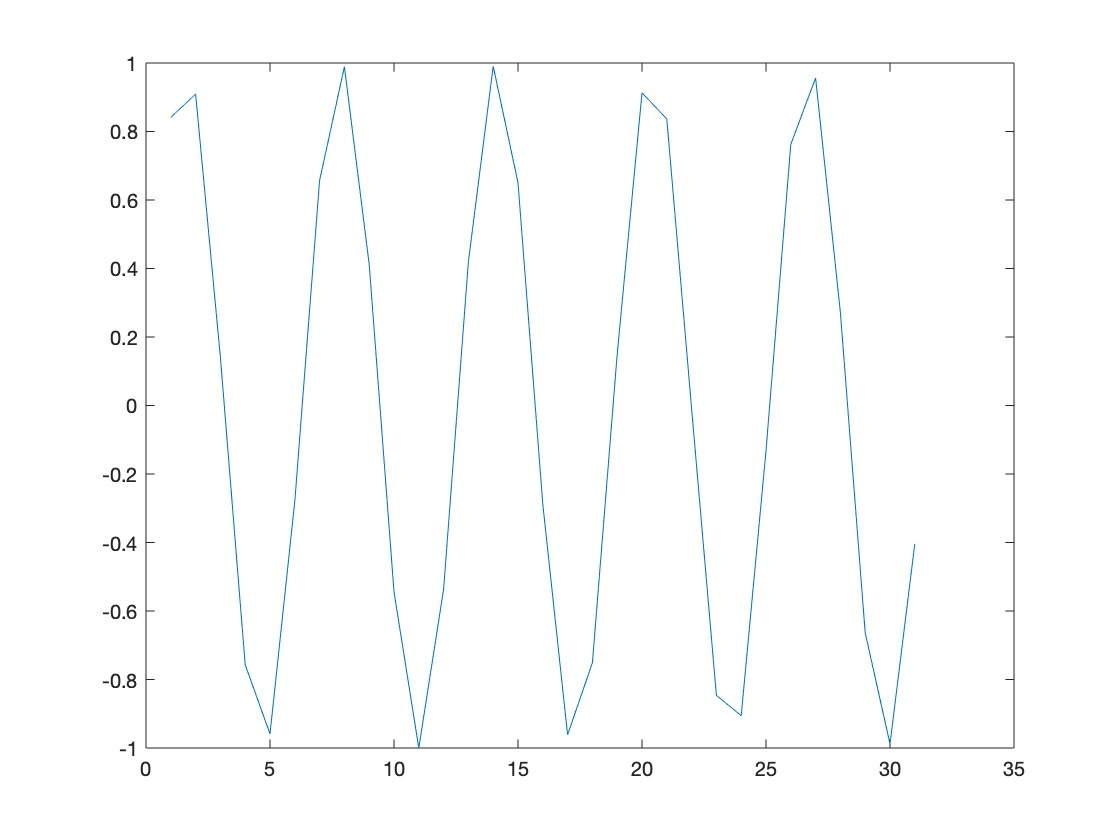

clear all;

%Basic plot of a funciton with bad resolution
x=1:10*pi;
y=sin(x);
plot(x,y)

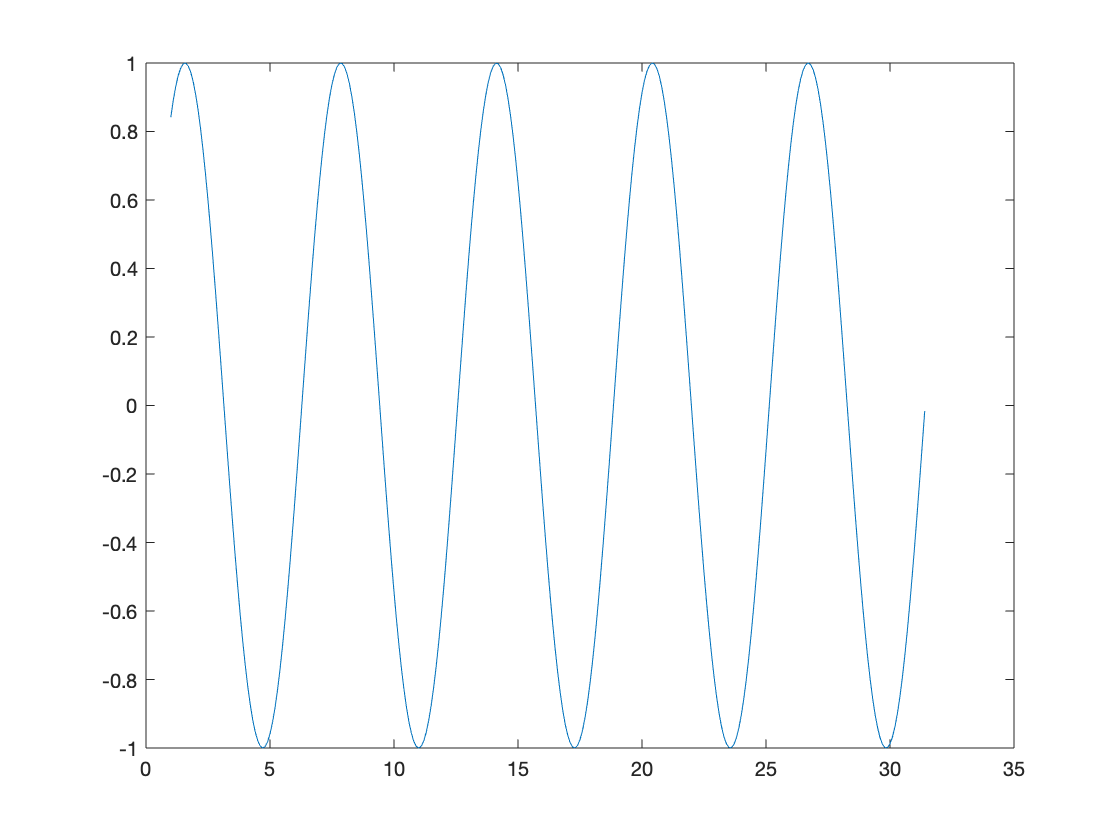


%To get finer resolution and a smoother plot
x=1:.1:10*pi;
y=sin(x);
plot(x,y);

If you are plotting in a script, the figure pops up in a new window. In the live scripts, figures will show up to the right or below.  Double click on the last plot to make it pop up.

Notice you can use the toolbar to edit the plot.  You can add a title, change the range, add axes titles, etc. Once you have the plot the way you like, it you can generate the code to reproduce the plot.

Manually changing the plot and generating code is one way to figure out how to produce a specific plot. The other way is to look carefully at the plot documentation (`doc plot`).  You can also look at [online examples](https://www.mathworks.com/products/matlab/plot-gallery.html). All techniques are useful.

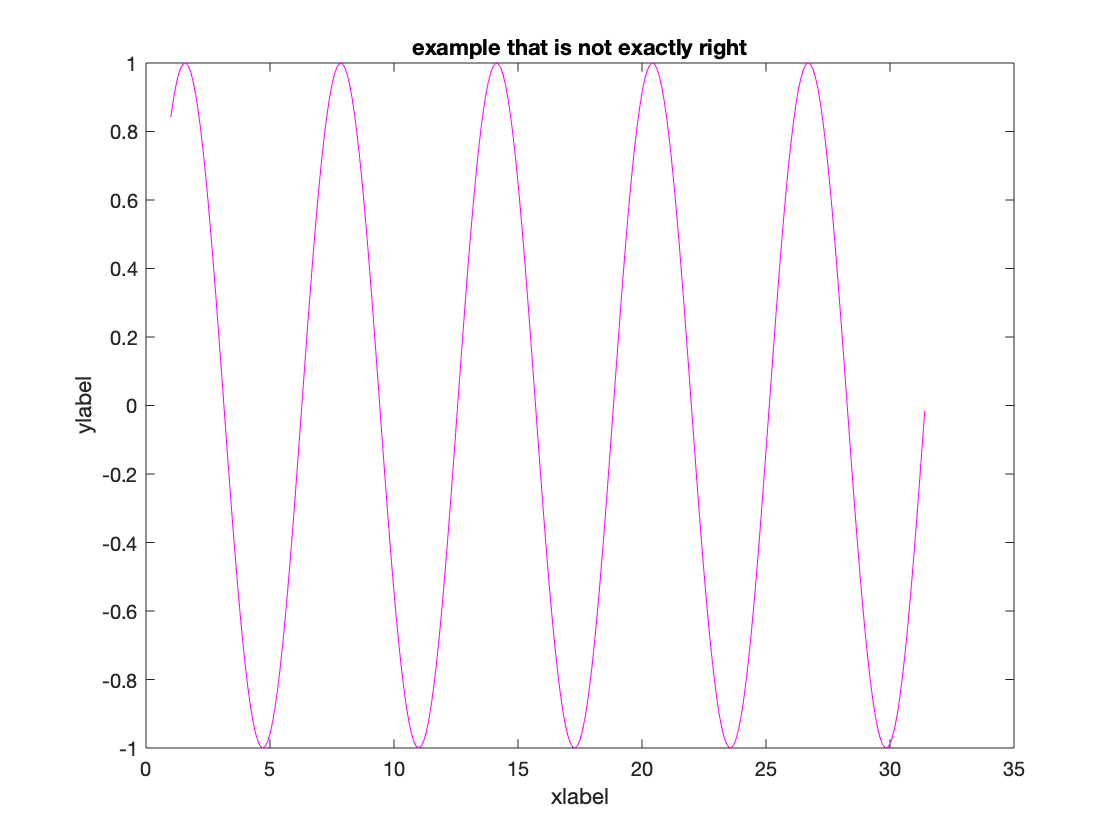

% Create plot, specify the color using an RGB scale (equal R and B)
plot(x,y,'Color',[1 0 1]);

% Create label for the axes
xlabel('xlabel');
ylabel('ylabel');

% Create title
title('example that is not exactly right');

## Plotting Functions

Another, perhaps more convenient way, to plot a function is to use `fplot`. Note the notation below.

clear all;

func=@(x)8*x+4*x.^2+3

func = function_handle with value:
    @(x)8*x+4*x.^2+3


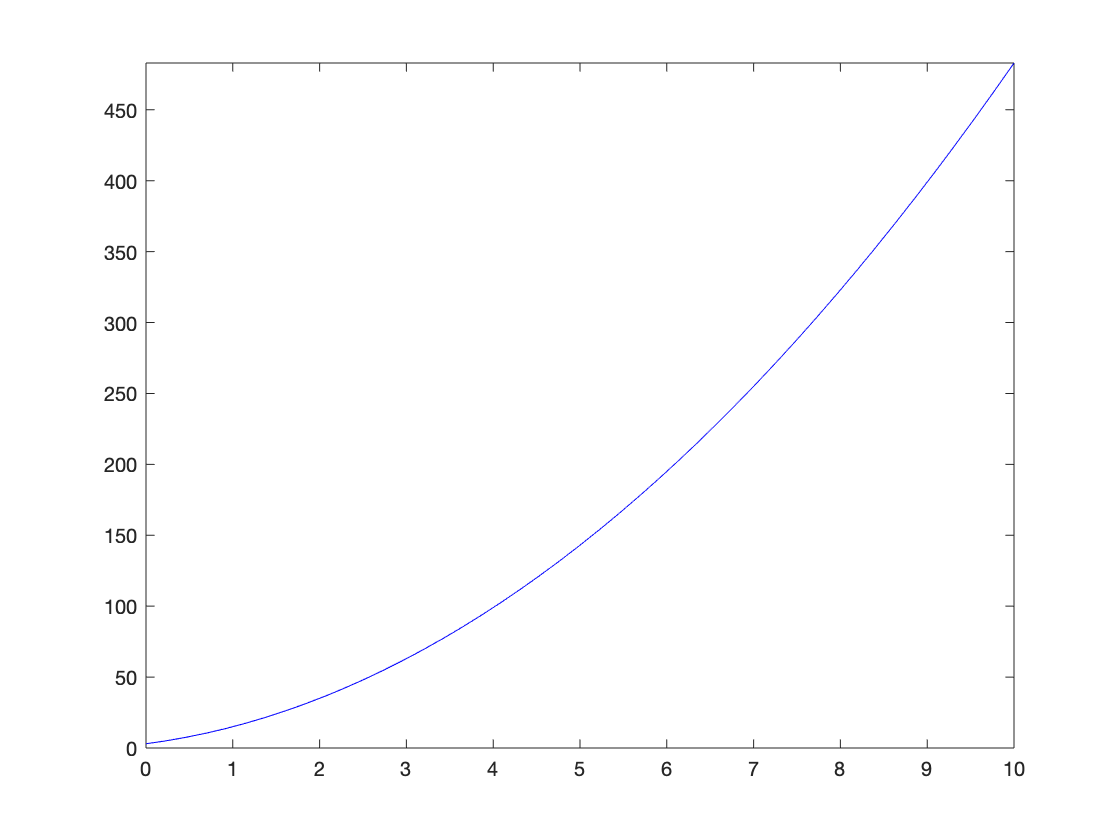

fplot(func,[0,10],'Color','Blue')

The @(x)8*x+4*x.^2+3, defines a function of variable x and [0,10] gives the limits of the plot.  Anything after that specifies properties of the plot.

## Plotting more than one set of data in the same plot

You can use one plot command to plot more than one set of data.

%Define an array for the x-values
x=1:.1:6*pi;

%Use functions to specify two y-values to plot
y1=sin(x);
y2=cos(x);

%Plot both functions by specifying the x- and y-vales of each
plot(x,y1,x,y2);

You can specify the properties of each line after the individual data sets, like this:

%The colors of lines are specified after the data
%If you want to change the line width you do it at the end of the plot command
%and it applies to both lines
plot(x,y1,'g',x,y2,'b','LineWidth',4);

Note that I am using shorthand ('g' and 'b') for the colors blue and green. The 'LineWidth' property changed the width of both lines.

Take a look at the plot documentation to get an idea about all the things you can specify about the look of your plot.

doc plot